EDO 1er orden

a = -1; % Intervalo = [a, b]
b = 2; 
y0 = -2; % Valor inicial
n = 10; % Nro de intervalos

f = @(t,y)(t.^2 - 3*y);  % dy/dt = f(t) <-- función

syms y(t) t

% Se plantea la edo ()
y(t) = dsolve(diff(y,t) == f(t,y), y(a) == y0); 
% Se transforma a función
SolEx = matlabFunction(y(t));

% EULER
[z]=EULER(f,a,b,y0,n);
solEuler=z(:,1:2);

% RUNGE KUTTA 2
[z]=RK2(f,a,b,y0,n);
solRK2=z(:,1:2);

% RUNGE KUTTA 4
z = RK4(f,a,b,y0,n);
solRK4 = z(:, 1:2)

solRK4 =   -1.000000000000000  -2.000000000000000
  -0.700000000000000  -0.686931875000000
  -0.400000000000000  -0.226909374195312
  -0.100000000000000  -0.082000255020967
   0.200000000000000  -0.031201779772176
   0.500000000000000   0.016282263802848
   0.800000000000000   0.097754364555103
   1.100000000000000   0.228539783747907
   1.400000000000000   0.414934713405531
   1.700000000000000   0.659525865318745


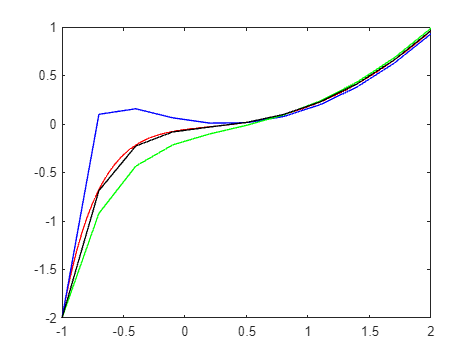


tt=a:0.01:b;

solEXC=SolEx(tt);
plot(tt,solEXC,'r',solEuler(:,1),solEuler(:,2),'b',solRK2(:,1),solRK2(:,2),'g', solRK4(:,1), solRK4(:,2), 'black')

function [z] = EULER(f,a,b,y0,n)
    %f=@(t,y)(t.^2-3*y);a=1;b=5;y0=2;n=4;
    h = (b-a)/n;
    t = [a:h:b]';
    z = [];

    for i = 1:(n+1)
        k1 = f(t(i),y0);
        y1 = y0 + k1*h;
        z = [z; t(i) y0 k1 y1];
        y0 = y1;
    end
end

function [z] = RK2(f,a,b,y0,n)
    %f=@(t,y)(t.^2-3*y);a=1;b=5;y0=2;n=4;
    h = (b-a)/n;
    t = [a:h:b]';
    z = [];

    for i = 1:(n+1)
        k1 = f(t(i), y0);
        k2 = f(t(i) + h, y0 + k1*h);
        y1 = y0 + (k1/2 + k2/2)*h;
        z = [z; t(i) y0 k1 k2 y1];
        y0 = y1;
    end
end

function z = RK4(f, a, b, y0, n)
    % f = función
    % a = primer valor del intervalo
    % b = último valor
    % y0 = valor inicial
    % n = intervalos

    h = (b-a)/n; % Tamaño de paso
    t = [a:h:b]'; % Valor de cada punto
    z = [];

    for i = 1:(n+1)
        k1 = f(t(i), y0);
        k2 = f(t(i) + h/2, y0 + k1*h/2);
        k3 = f(t(i) + h/2, y0 + k2*h/2);
        k4 = f(t(i) + h, y0 + k3*h);   
        y1 = y0 + (k1/6 + k2/3 + k3/3 + k4/6)*h;
        z = [z; t(i) y0 k1 k2 y1];
        y0 = y1;
    end
end